**Adrian Cristian Crisan**

[https://drive.matlab.com/sharing/67e401c0-ccbc-48e9-9c17-19f694be4e96](https://drive.matlab.com/sharing/67e401c0-ccbc-48e9-9c17-19f694be4e96)

# Milling and Welding Todo

I have solved for you as an example the drilling task. Similar procedure ought to be done with welding task

See the video: [https://youtu.be/cVZWm9ORY30](https://youtu.be/cVZWm9ORY30)

As you can see in the video a Robot Arm perform three task. Only two tasks are shown: 

- Make a hole in a cylinder by drilling it. Observe that the tool mantain the same orientation during the drilling task.

- Insertion of a smaller cylinder not recorder here. 

- Welding the two cylinder. Observe that the tool always form a 45º among the two cylinder axis

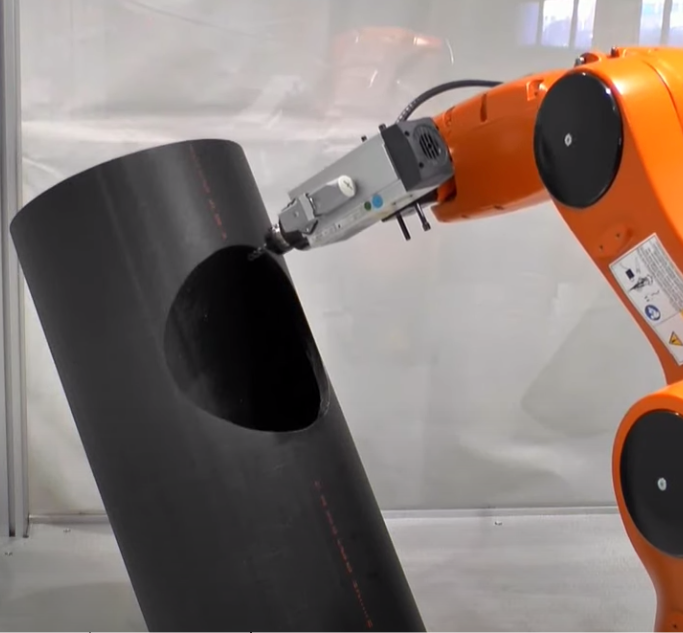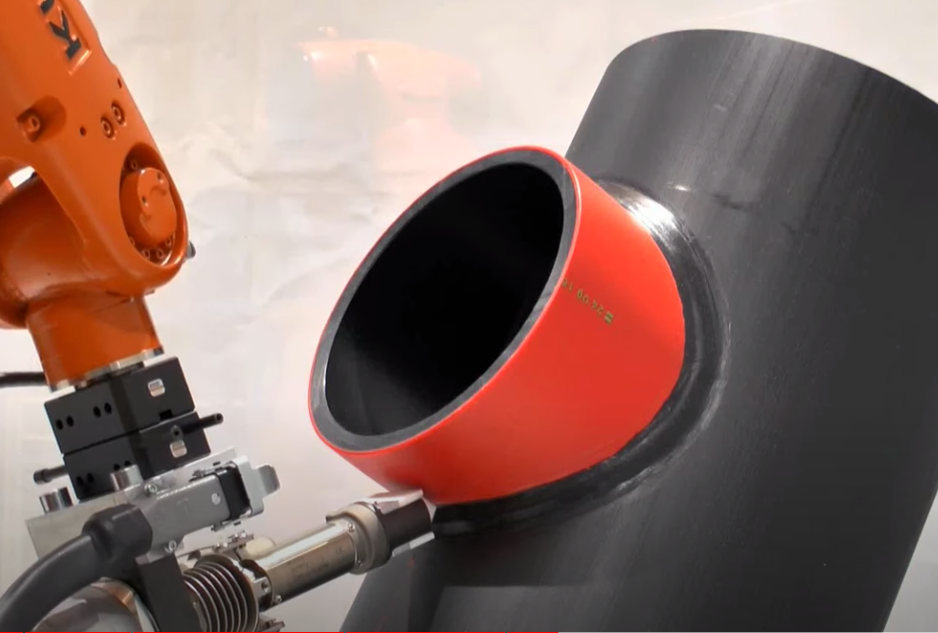

## Load the cylinder data

clear;
close all;
clf
load('F_V_cylinder.mat');

## **Plot the robot to initial position**

Pay attention how to move the robot base and add a tool

radius = 0.20;
n = 200;
mdl_puma560
p560.base = transl(-0.1, 0, 0)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.1, 0, 0), RPY/xyz = (0, 0, 0) deg               
 


p560.tool = transl(0,0,0.15)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, slowRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (-0.1, 0, 0), RPY/xyz = (0, 0, 0) deg               
tool:    t = (0, 0, 0.15), RPY/xyz = (0, 0, 0) deg               
 


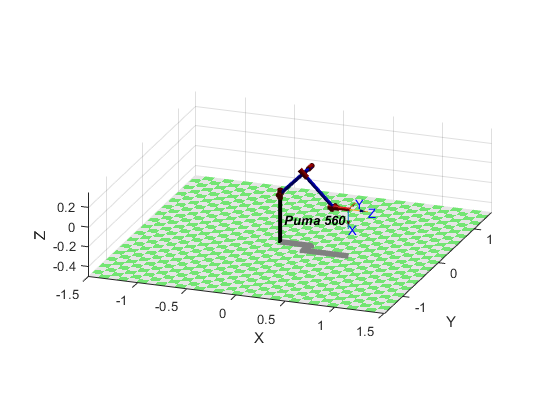

p560.plot(qn, 'zoom', 2.5, 'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1], 'view', [20 20]);
axis equal
hold on

## Visualize the cylinder

This is the cylinder that we will drill

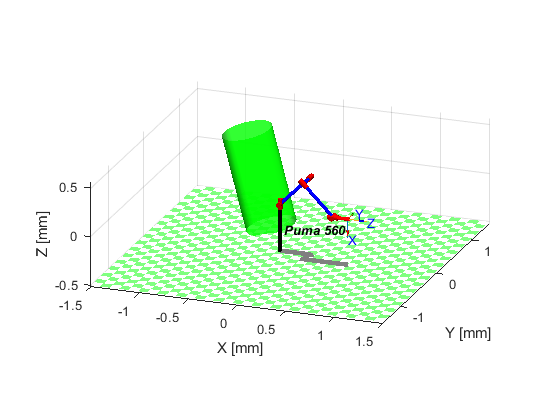

Cy_scale = 0.25;
CY_pose = transl([-0.3 0.3 -0.35]) * troty(-pi/6) * trotx(-pi/6);
V_cy_drill = CY_pose * [Cy_scale .* V_cy'; ones(1, length(V_cy))];
FVsPlot(F_cy,V_cy_drill(1:3,:)',[0 1 0])

## Visualize the other cylinder

This are the cylinders that we will weld

The first one is the main cylinder

Cy_scale2 = 0.25;
CY_pose2 = transl([0.3 0.3 -0.35]) * troty(pi/6) * trotx(-pi/6);
V_cy_drill2 = CY_pose2 * [Cy_scale2 .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy, V_cy_drill2(1:3, :)', [0 1 0])

This second one is the welded cylinder

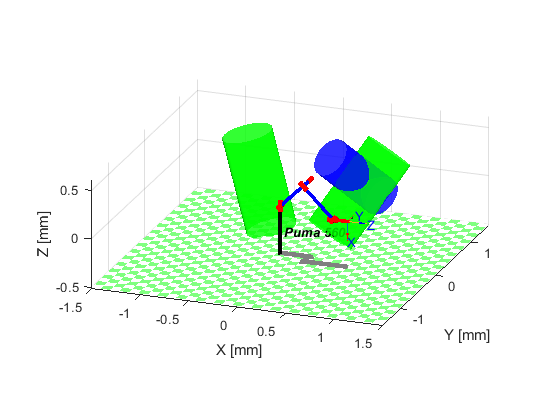

Cy_scale3 = 0.2;
CY_pose3 = CY_pose2 * transl(0,0,0.6) * trotx(pi/2) * troty(-pi/4) * transl(0,0,-0.25);

V_cy_drill3 = CY_pose3 * [Cy_scale3 .* V_cy'; ones(1,length(V_cy))];
FVsPlot(F_cy, V_cy_drill3(1:3,:)', [0 0 1])

## Draw drill task profile

Drill hole center 'D_h_c'

D_h_c = CY_pose * transl(0,0,0.6) * trotx(-pi/2) * troty(-pi/4) * transl(0,0,-0.25);

Drill poses

n=60

n = 60

for i=1:n
Drill_Pose(:,:,i)= D_h_c*trotz(2*pi*i/n)*transl(radius, 0,0);
end

Plotting Drill poses. Notice 'z' axis of the poses 

cir=transl(Drill_Pose)'

cir =    -0.2849   -0.2785   -0.2740   -0.2715   -0.2709   -0.2723   -0.2757   -0.2809   -0.2881   -0.2970   -0.3076   -0.3198   -0.3334   -0.3483   -0.3643   -0.3813   -0.3990   -0.4173   -0.4360   -0.4548   -0.4736   -0.4922   -0.5103   -0.5277   -0.5443   -0.5599   -0.5743   -0.5873   -0.5988   -0.6087   -0.6169   -0.6233   -0.6278   -0.6303   -0.6309   -0.6295   -0.6261   -0.6209   -0.6137   -0.6048   -0.5942   -0.5820   -0.5684   -0.5535   -0.5375   -0.5205   -0.5028   -0.4845   -0.4658   -0.4470
    0.5583    0.5459    0.5325    0.5181    0.5030    0.4872    0.4710    0.4545    0.4380    0.4215    0.4054    0.3896    0.3746    0.3603    0.3469    0.3347    0.3236    0.3140    0.3057    0.2991    0.2940    0.2906    0.2890    0.2890    0.2908    0.2943    0.2995    0.3063    0.3147    0.3244    0.3356    0.3479    0.3613    0.3757    0.3908    0.4066    0.4228    0.4393    0.4558    0.4723    0.4884    0.5042    0.5193    0.5336    0.5469    0.5592    0.5702    0.5799    0.5881   

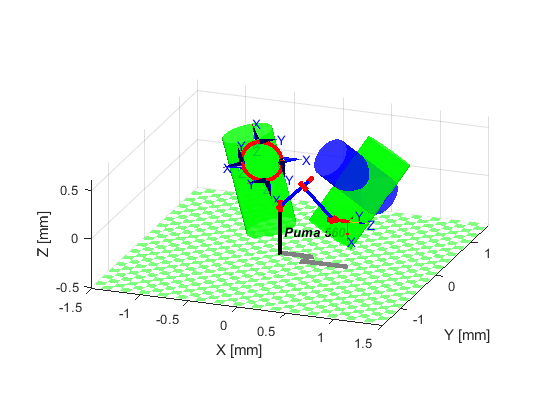

hold on
plot3(cir(1,:), cir(2,:), cir(3,:),'r','LineWidth',3);
%axis([-1.5 1.5 -1.5 1.5 -0.5 1])
axis equal
trplot(Drill_Pose(:,:,1), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,15), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,30), 'length',0.2, 'arrow')
trplot(Drill_Pose(:,:,45), 'length',0.2, 'arrow')

## Recording the drilling task

Animate: saving video --> Puma_drilling_task.mp4 with profile 'MPEG-4'


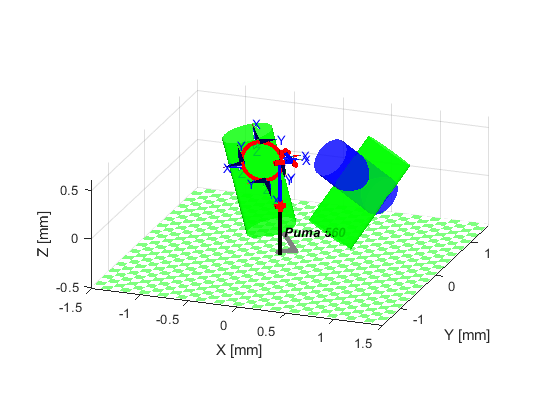

Q = p560.ikine6s(Drill_Pose, 'run');
p560.plot(Q, 'view', [20 20], 'zoom', 1.5, 'workspace', [-1.5 1.5 -1.5 1.5 -0.5 1], ...
    'trail', '-', 'jaxes', 'zoom', 2, 'movie', 'Puma_drilling_task.mp4')

## Draw welding task profile

Welding hole center 'W_h_c'

W_h_c = CY_pose2 * transl(0,0,0.6) * trotx(pi/2) * troty(-pi/4) * transl(0,0,0.26)

W_h_c =     0.7891    0.4330   -0.4356    0.4466
   -0.6124    0.5000   -0.6124    0.4408
   -0.0474    0.7500    0.6597    0.2715
         0         0         0    1.0000


Generating points

r=0.2;
t=0:pi/16:2*pi;
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))]

cp0 =     0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000   -0.0390   -0.0765   -0.1111   -0.1414   -0.1663   -0.1848   -0.1962   -0.2000   -0.1962   -0.1848   -0.1663   -0.1414   -0.1111   -0.0765   -0.0390   -0.0000    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000
         0    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000   -0.0390   -0.0765   -0.1111   -0.1414   -0.1663   -0.1848   -0.1962   -0.2000   -0.1962   -0.1848   -0.1663   -0.1414   -0.1111   -0.0765   -0.0390   -0.0000
    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000    0.1962    0.1848    0.1663    0.1414    0.1111    0.0765    0.0390    0.0000    0.0390    0.0765    0.1111    0.1414    0.1663    0.1848    0.1962    0.2000
 

Plotting Welding poses

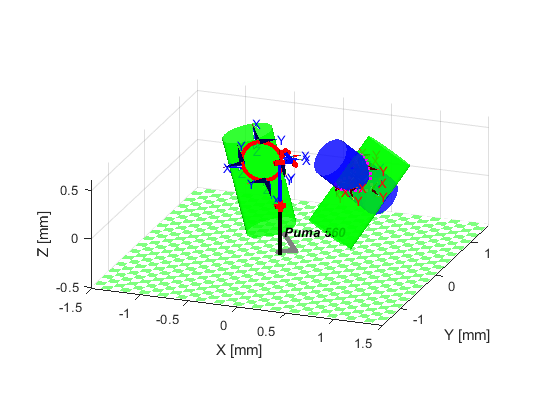

% Translation of the welding
T0 = transl(0.5, 0.5, 0.2) * trotz(pi/4) * troty(-pi/4) * transl(0, 0, -0.1);
cp1 = T0 * cp0;

% Draws the welding
scatter3(cp1(1,:), cp1(2,:), cp1(3,:),'.', 'm', 'LineWidth', 2)

% Reference frame
trplot(T0, 'length', 0.2, 'arrow')

T1 = T0 * transl(0, 0.2, 0) * troty(pi) * trotx(pi/4);
trplot(T1, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T2 = T0 * transl(-0.141421, 0.141421, 0.141421) * troty(pi) * trotz(-pi/4) * trotx(pi/4);
trplot(T2, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T3 = T0 * transl(-0.2, 0, 0.2) * troty(pi) * trotz(-pi/2) * trotx(pi/4);
trplot(T3, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T4 = T0 * transl(-0.141421, -0.141421, 0.141421) * trotz(-pi/4) * trotx(-3*pi/4);
trplot(T4, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T5 = T0 * transl(0, -0.2, 0) * trotx(-3*pi/4);
trplot(T5, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T6 = T0 * transl(0.141421, -0.141421, 0.141421) * trotz(pi/4) * trotx(-3*pi/4);
trplot(T6, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T7 = T0 * transl(0.2, 0, 0.2) * troty(pi) * trotz(pi/2) * trotx(pi/4);
trplot(T7, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

T8 = T0 * transl(0.141421, 0.141421, 0.141421) * troty(pi) * trotz(pi/4) * trotx(pi/4);
trplot(T8, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')


Welding_Pose(:,:,1) = T1;
Welding_Pose(:,:,2) = T2;
Welding_Pose(:,:,3) = T3;
Welding_Pose(:,:,4) = T4;
Welding_Pose(:,:,5) = T5;
Welding_Pose(:,:,6) = T6;
Welding_Pose(:,:,7) = T7;
Welding_Pose(:,:,8) = T8;





Q = p560.ikine6s(Welding_Pose, 'run');


%p560.plot(Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1])

## Recording the welding task

% Q = p560.ikine6s(Welding_Pose, 'run');
% p560.plot( Q,'view',[150 45], 'zoom',1.5,'workspace', [-1 0.5 -0.5 0.5 -1 1],...
%              'trail','-','jaxes','zoom',2,'movie','Puma_welding_task.mp4')

## Only Welding points

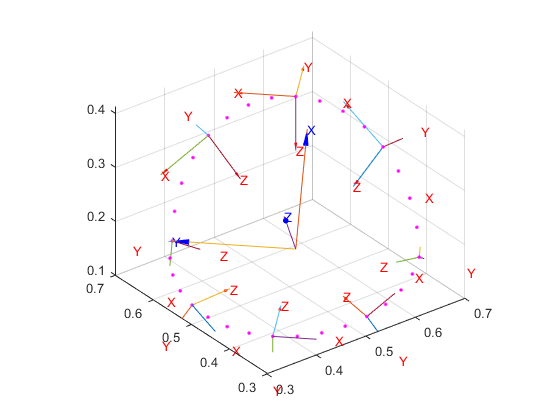

figure
T0 = transl(0.5, 0.5, 0.2) * trotz(pi/4) * troty(-pi/4) * transl(0, 0, -0.1);
cp1 = T0 * cp0;
scatter3(cp1(1,:), cp1(2,:), cp1(3,:),'.', 'm', 'LineWidth', 2)

hold on

% Reference point
trplot(T0, 'length', 0.2, 'arrow')

trplot(T1, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T2, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T3, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T4, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T5, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T6, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T7, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')
trplot(T8, 'length', r/2, 'arrow', 'width', 0.5, 'color','r')

## Functions

function T_b_a=FVsPlot(F,V,color)
patch('Faces',F,'Vertices',V,'FaceColor',color, ...
         'FaceAlpha',0.8,...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('dull');

grid on
xlabel 'X [mm]'
ylabel 'Y [mm]'
zlabel 'Z [mm]'
axis equal
end